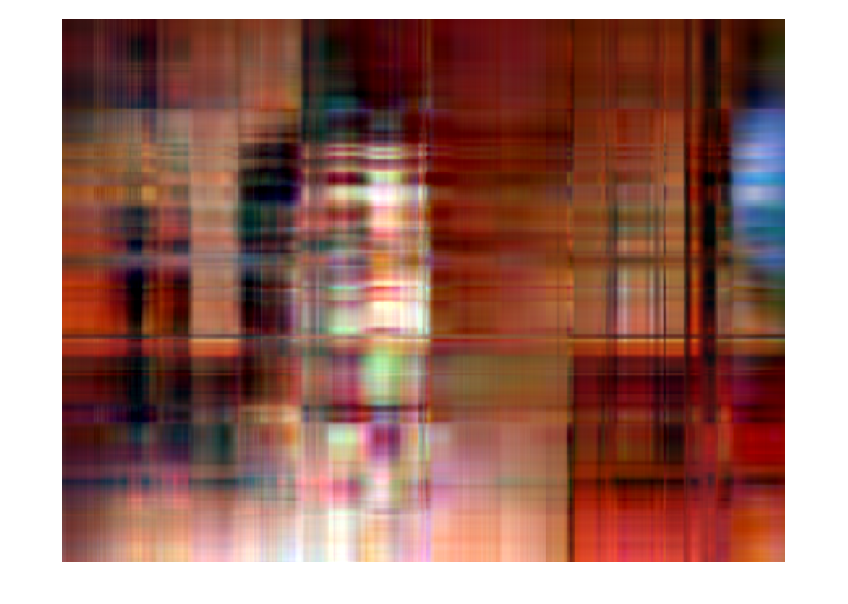

imagePath = 'guy';
imageExtension = '.jpg';

originalImage = imread([imagePath imageExtension]);

k = 5;
compressedImage = compressImage(originalImage, k);

imshow(compressedImage);


saveCompressedImage(compressedImage, imagePath, imageExtension, k);

function image = compressImage(fullImage, maxDim)
    [redChannel, greenChannel, blueChannel] = imageToChannels(fullImage);

    redChannel = compressChannel(redChannel, maxDim);
    greenChannel = compressChannel(greenChannel, maxDim);
    blueChannel = compressChannel(blueChannel, maxDim);

    image = imageFromChannels(redChannel, greenChannel, blueChannel);
end

function channel = compressChannel(channel, maxDim)
    tolerance = 1e-5;

    [U, S, V] = svdsketch( ...
        double(channel), ...
        tolerance, ...
        'MaxSubspaceDimension', ...
        maxDim);

    channel = uint8(U * S * V');
end

function [red, green, blue] = imageToChannels(image)
    red = image(:, :, 1);
    green = image(:, :, 2);
    blue = image(:, :, 3);
end

function image = imageFromChannels(red, green, blue)
    image = cat(3, red, green, blue);
end

function saveCompressedImage(image, imagePath, imageExtension, k)
    mainFolder = '/home/glebari/linear_algebra_labs/lab_6/';

    newPath = [imagePath '_' 'compressed' '_' num2str(k) imageExtension];
    imwrite(image, fullfile(mainFolder, newPath));
end